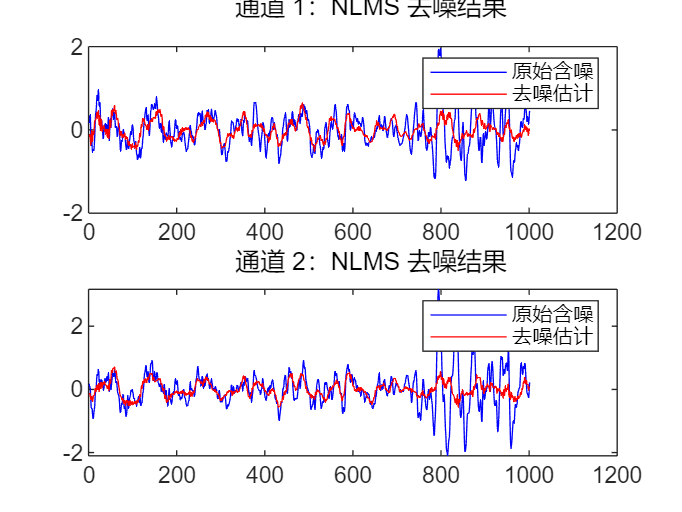

%% NLMS 自适应滤波实现：Homework 2 - Part a
clear; close all; clc;

% 加载数据
load('Hw2a.mat');  % 包含 Sin_a, Sn_ref_a, fs

%% 参数设置
filter_order = 64;       % 滤波器阶数
mu = 0.01;               % 步长，越大收敛越快，太大会震荡
epsilon = 1e-6;          % 防止除以0的正则项
[N, M] = size(Sin_a);    % M=2 为立体声通道数

Sin_est = zeros(N, M);   % 存储输出（去噪信号）

%% NLMS 主循环
for ch = 1:M
    x = Sn_ref_a(:, ch);      % 噪声参考输入
    d = Sin_a(:, ch);         % 含噪信号
    a = zeros(filter_order, 1);  % 初始化滤波器权重
    e = zeros(N, 1);          % 误差信号输出

    for n = filter_order:N
        x_n = x(n:-1:n-filter_order+1);     % 当前窗口输入
        y = a' * x_n;                       % 噪声估计
        e(n) = d(n) - y;                    % 误差（即干净信号估计）
        norm_factor = epsilon + x_n' * x_n; % 能量归一化因子
        a = a + (mu / norm_factor) * e(n) * x_n;  % NLMS 权重更新
    end

    Sin_est(:, ch) = e;  % 保存去噪信号
end

figure;
for ch = 1:M
    subplot(M,1,ch);
    plot(Sin_a(N-111000:N-110000,ch), 'b'); hold on;
    plot(Sin_est(N-111000:N-110000,ch), 'r');
    legend('原始含噪','去噪估计');
    title(['通道 ', num2str(ch), '：NLMS 去噪结果']);
end

%% 播放结果
disp('▶ 播放去噪后的 NLMS 估计信号...');

▶ 播放去噪后的 NLMS 估计信号...


sound(Sin_est, fs);
disp('▶ 播放完毕');

▶ 播放完毕


pause(length(Sin_est)/fs + 1);
